#### 1. Função de Transferência do sistema

Entrada 0-255 -> R=156

Saida 0-1023  -> Y = 600

Tensao 0-5v

uk -> 0 - 2.51

Vap -> 0 -255

Vap = uk * 255/2.51

a = 10.4167;
s = tf('s');
Kp = 595;
Ts = 0.008; % Período de amostragem (Ts = 8ms)
Gp = a * Kp /(s+a);
Gp_zpk = zpk(Gp)

Gp_zpk =
 
   6197.9
  ---------
  (s+10.42)
 
Continuous-time zero/pole/gain model.
Model Properties


#### 2. Modelo em espaço de estado


$$\dot{\mathbf{x}}(t) = \mathbf{A}\mathbf{x}(t) + \mathbf{B}\mathbf{u}(t) \\
\mathbf{y}(t) = \mathbf{C}\mathbf{x}(t) + \mathbf{D}\mathbf{u}(t)
$$


[num, den] = tfdata(Gp, 'v'); 
[Ac, Bc, Cc, Dc] = tf2ss(num, den);

#### 3. Sistem em espaço de estados

sys = ss(Ac, Bc, Cc, Dc) % Sistema tempo contínuo

sys =
 
  A = 
           x1
   x1  -10.42
 
  B = 
       u1
   x1   1
 
  C = 
         x1
   y1  6198
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


#### 3.1 Resposta ao degrau

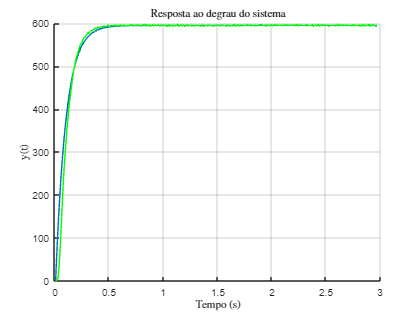

dados = readtable('./Remodelando/saida-156.csv');

t8ms = 1:length(dados.Tempo);
t8ms = t8ms * 8e-3;

[yp, tp] = step(sys, t8ms);

f = figure;
hold on;
plot(tp, yp);
plot(t8ms, dados.Saida, color='g');
title('Resposta ao degrau do sistema', 'Interpreter', 'latex');
ylabel('y(t)', 'Interpreter', 'latex');
xlabel('Tempo (s)', 'Interpreter', 'latex');
grid on;
exportgraphics(f, './Resultados/Sistema.pdf', 'ContentType', 'vector');

#### 4.  Projetando o Controlador

**4.1 Avaliando Controlabilidade e Observabilidade**

% Controlabilidade

Sz = Bc;

if length(Sz)==1
    if Sz~=0
        fprintf("É controlável.");
    else
        fprintf("Não é controlável.");
    end
else
    if det(Sz)~=0
        fprintf("É controlável.");
    else
        fprintf("Não é controlável.");
    end
end

É controlável.

% Convertendo para FCC

Q1_c = 1 * Sz^(-1);

Q_c = Q1_c;

Ax_fcc = Q_c*Ac*Q_c^(-1)

Ax_fcc = -10.4167

Bx_fcc = Q_c*Bc

Bx_fcc = 1

Cx_fcc = Cc*Q_c^(-1)

Cx_fcc = 6.1979e+03

Sx = Bx_fcc;

P_c = Sz*Sx^(-1);

% Observabilidade

Vz = Cc;

if length(Vz)==1
    if Vz~=0
        fprintf("É observável.");
    else
        fprintf("Não é observável.");
    end
else
    if det(Vz)~=0
        fprintf("É observável.");
    else
        fprintf("Não é observável.");
    end
end

É observável.

% Convertendo para FCO

Q1_o = Cc^(-1) * 1;

Q_1_o = Q1_o;

Q_o = Q_1_o^(-1);

Ax_fco = Q_o*Ac*Q_1_o

Ax_fco = -10.4167

Bx_fco = Q_o*Bc

Bx_fco = 6.1979e+03

Cx_fco = 1

Cx_fco = 1

Vx = Cx_fco;

P_o = Vz^(-1)*Vx;

**4.2 Definindo Especificações de Desempenho **

info = stepinfo(dados.Saida, t8ms);

% Tempo de acomodação a 2%
ts_orig = info.SettlingTime

ts_orig = 0.3496

% Polos desejados
cf = Kp;
cmax = Kp + 50;

% Ultrapassagem percentual.
up = ((cmax-cf)/cf) * 100 

up = 8.4034

% Tempo de acomodação.
ts = 1.5 * ts_orig 

ts = 0.5244

qsi = (-log(up/100))/(sqrt(pi^2+log(up/100)^2));

% Calcula o fator de amortecimento
% requerido.

wn = 4/(qsi*ts); % Calcula a frequência natural
% requerida.

[numd,dend] = ord2(wn,qsi); % Produz um sistema de
% segunda ordem que atende aos
% requisitos de resposta transitória.

r = roots(dend); % Usa o denominador para
% especificar os polos dominantes.

polos = [r(1) r(2)] % Especifica a posição de todos

polos =   -7.6278 + 9.6761i  -7.6278 - 9.6761i


% os polos.

eq_caracteristica_desejada = poly(polos);

fprintf('Equação característica desejada:\n');

Equação característica desejada:


fprintf('s^2 + %.2fs + %.2f\n', ...
    eq_caracteristica_desejada(2), ...
    eq_caracteristica_desejada(3));

s^2 + 15.26s + 151.81


**4.3 Adicionando Ação Integral**

% Construção do sistema aumentado
A_hat = [Ac     zeros(size(Ac,1),1);
         -Cc     0]

A_hat = 1.0e+03 *

   -0.0104         0
   -6.1979         0



B_hat = [Bc;
         0]

B_hat =      1
     0


C_hat = [Cc 0]

C_hat = 1.0e+03 *

    6.1979         0


% Polos desejados (reutilizados ou altere para adicionar um terceiro)
% Adicionando um polo extra mais à esquerda para o integrador


% Projeto do ganho com realimentação de estados aumentados
K_hat = acker(A_hat, B_hat, polos);

% Extração dos ganhos K e Ki
K  = K_hat(1:end-1)

K = 4.8388

Ki = -K_hat(end)

Ki = 0.0245


% Sistema em malha fechada com integrador
A_hat_cl = [Ac - Bc*K, Bc*Ki;
            -Cc      ,  0];

B_hat_cl = [0; 1];  % Entrada de referência
C_hat_cl = [Cc 0];
D_hat_cl = 0;

sys_cl = ss(A_hat_cl, B_hat_cl, C_hat_cl, D_hat_cl);
sys_tf = tf(sys_cl);  % Converte espaço de estados para FT

[y, tOut] = step(sys_tf, t8ms);

zpk(sys_tf)           % Exibe zeros, polos e ganho

ans =
 
          151.81
  ----------------------
  (s^2 + 15.26s + 151.8)
 
Continuous-time zero/pole/gain model.
Model Properties


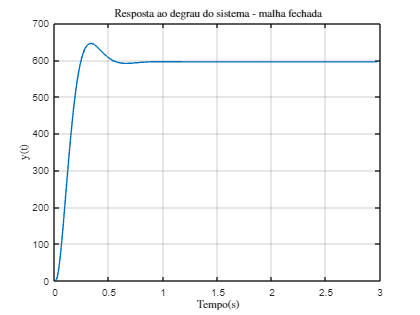


% Plotagem dos estados
f = figure;
plot(tOut, y*Kp);
title('Resposta ao degrau do sistema - malha fechada', 'Interpreter', 'latex');
ylabel('y(t)', 'Interpreter', 'latex');
xlabel('Tempo(s)','Interpreter', 'latex');
grid on;
exportgraphics(f, './Resultados/Cotrolador.pdf', 'ContentType', 'vector')

**4.4  Análise das EDS**

info = stepinfo(y, tOut);

% Tempo de acomodação a 2%
ts_pred = info.SettlingTime;
UP = info.Overshoot;
fprintf('Tempo de acomodação: %.4f ms\n', ts_pred);

Tempo de acomodação: 0.4930 ms


fprintf('Ultrapassagem percentual : %.4f ms\n', UP);

Ultrapassagem percentual : 8.3964 ms


### **5. Projetando o Observador**

#### **5.1 Equação caracteristica desejada do observador**

**(Ts 10x menor do que o do controlar)**

Ts_obs = (ts / 10);
wn_obs = 4/(qsi*Ts_obs); % Calcula a frequência natural

polo_o = qsi*wn_obs

polo_o = 76.2777

#### **5.2 Ganho do observador**

L = -place(Ac', Cc', polo_o)'

L = 0.0140

#### **5.3 Simulação do observador**


$$ \dot{x}(t) = A x(t) + Bu(t)\\
 \dot{\hat{x}}(t) = (A-LC) \hat{x}(t) + LC x(t) + Bu(t)$$



$$    \dot{\hat{x}} = A_o \hat{x} + B_o z \\
    y_o = C_o \hat{x}
$$
  


$$A_o =A-\textrm{LC}$$
 
$$;B_o =\left\lbrack \begin{array}{cc}
B & L
\end{array}\right\rbrack$$

$$;C_o =I_n$$

$$;z=\left\lbrack \begin{array}{c}
u\\
y
\end{array}\right\rbrack$$


o vetor z que consiste na entrada e na saída do sistema é a entrada do observador

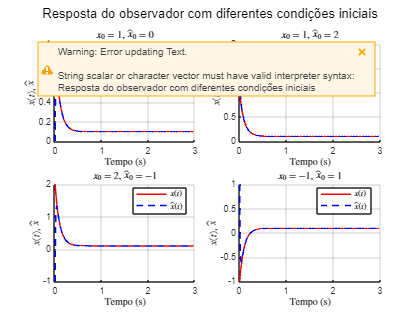

input = ones(size(t8ms));

% Matriz do sistema e observador (1x1)
Acl = Ac - L * Cc;
Aobserver = Acl;
Bobserver = [Bc L];
Cobserver = Cc; 
Dobserver = Dc;

% Criar sistema observador
sysObserver = ss(Aobserver, Bobserver, Cobserver, Dobserver);

% Pares de condições iniciais: [x0_true, x0_obs]
init_pairs = [
    1, 0;
    1, 2;
    2, -1;
    -1, 1
];

% Figura com subplots
f = figure;
for i = 1:4
    x0true = init_pairs(i,1);
    x0obs  = init_pairs(i,2);

    % Simular sistema real
    [yTrue, timeTrue, xTrue] = lsim(sys, input, t8ms, x0true);

    % Entrada combinada u e y para o observador
    inputUY = [input; yTrue'];

    % Simular observador
    [yObserver, timeObserver, xObserver] = lsim(sysObserver, inputUY, t8ms, x0obs);

    % Plot
    subplot(2,2,i);
    hold on;
    plot(timeTrue, xTrue(:,1), 'r', 'LineWidth', 1.5, 'DisplayName', '$x(t)$');
    plot(timeObserver, xObserver(:,1), 'b--', 'LineWidth', 1.5, 'DisplayName', '$\hat{x}(t)$');
    title(sprintf('$x_0 = %g$, $\\hat{x}_0 = %g$', x0true, x0obs), 'Interpreter', 'latex');
    xlabel('Tempo (s)', 'Interpreter', 'latex');
    ylabel('$x(t)$, $\hat{x}$', 'Interpreter', 'latex');
    legend('Interpreter', 'latex', 'Location', 'best');
    grid on;
    hold off;
end

sgtitle('Resposta do observador com diferentes condições iniciais', 'Interpreter', 'latex');
exportgraphics(f, './Resultados/Observador.pdf', 'ContentType', 'vector');

#### 3. Discretização das equações de estado

 
$$\mathbf{x}[k+1] = \mathbf{A}_d \, \mathbf{x}[k] + \mathbf{B}_d \, \mathbf{u}[k] \\
\mathbf{y}[k] = \mathbf{C}_d \, \mathbf{x}[k]
$$


n = size(Ac);

#### Malha aberta

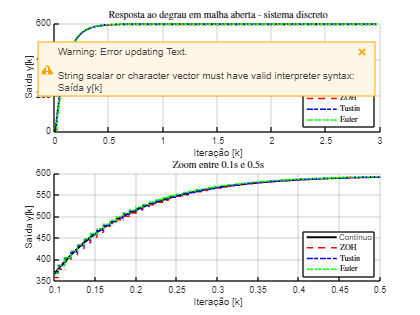

sys_zoh = c2d(sys,Ts,'zoh');
sys_tustin = c2d(sys,Ts,'tustin');

Aeuler =  eye(n) + Ts * sys.A; 
Beuler =  Ts * sys.B;
Ceuler = sys.C;
Deuler = sys.D;
sys_euler = ss(Aeuler, Beuler, Ceuler, Deuler, Ts);

t = t8ms;
u = ones(size(t)); % Degrau unitário

% Respostas dos sistemas
[y_cl, time_cl, x_cl]               = lsim(sys, u, t);       % Contínuo
[y_zoh, time_zoh, x_zoh]            = lsim(sys_zoh, u, t);      % Discretizado ZOH
[y_tustin, time_tustin, x_tustin]   = lsim(sys_tustin, u, t);   % Discretizado Tustin
[y_euler, time_euler, x_euler]      = lsim(sys_euler, u, t);    % Discretizado Euler

% Criação da figura com dois subplots
f = figure;

% --- Subplot 1: Janela de tempo completa
subplot(2,1,1);
hold on;
plot(t, y_cl,     'k-',  'LineWidth', 2,   'DisplayName', 'Contínuo');
stairs(t, y_zoh,   'r--', 'LineWidth', 1.5, 'DisplayName', 'ZOH');
stairs(t, y_tustin,'b-.', 'LineWidth', 1.5, 'DisplayName', 'Tustin');
stairs(t, y_euler, 'g:',  'LineWidth', 1.5, 'DisplayName', 'Euler');
legend('Location','best', 'Interpreter','latex');
xlabel('Iteração [k]');
ylabel('Saída y[k]', 'Interpreter','latex');
title('Resposta ao degrau em malha aberta - sistema discreto', 'Interpreter','latex');
grid on;

% --- Subplot 2: Zoom em 0.1 a 0.5 segundos
subplot(2,1,2);
hold on;
plot(t, y_cl,     'k-',  'LineWidth', 2,   'DisplayName', 'Contínuo');
stairs(t, y_zoh,   'r--', 'LineWidth', 1.5, 'DisplayName', 'ZOH');
stairs(t, y_tustin,'b-.', 'LineWidth', 1.5, 'DisplayName', 'Tustin');
stairs(t, y_euler, 'g:',  'LineWidth', 1.5, 'DisplayName', 'Euler');
xlim([0.1 0.5]);
legend('Location','best', 'Interpreter','latex');
xlabel('Iteração [k]');
ylabel('Saída y[k]', 'Interpreter','latex');
title('Zoom entre 0.1s e 0.5s', 'Interpreter','latex');
grid on;

% Exporta tudo em um único PDF
exportgraphics(f, './Resultados/Discretização.pdf', 'ContentType', 'vector');

## Aplicando controlador e observador dicretizados

Sistema

    
$$\mathbf{x}[k+1] = \mathbf{A}_d  \cdot \ \mathbf{x}[k] + \mathbf{B}_d \cdot \ \mathbf{u}[k] \\
\mathbf{y}[k] = \mathbf{C}_d \cdot \mathbf{x}[k]  +  \mathbf{D}_d \, \mathbf{u}[k]
$$


Lei de controle        


$$\mathbf{u}[k] = -K \cdot \mathbf{x}[k] + K_i \cdot x_n[k]$$


Estado do integrador


$$x_n[k] = x_n[k-1] + Ts \cdot e[k-1];$$


Estado estimado pelo observador 


$$   \mathbf{{\hat{x}}}[k] = (\mathbf{A_d}- L \cdot \mathbf{C_d}) \cdot   \mathbf{{\hat{x}}}[k-1] + \mathbf{B_d}  \cdot \mathbf{u}[k-1] + L \cdot \mathbf{y}[k-1] \\
    y_o = \mathbf{C_d} \mathbf{\hat{x}}[k] + \mathbf{D_d} \cdot \mathbf{u}[k]
$$


Nova lei de controle com estado estimado


$$\mathbf{u}[k] = -K \cdot \mathbf{\hat{x}}[k] + K_i \cdot x_n[k]$$


N = length(t8ms);

#### I. ZOH

[y_zoh_cl, e_log_zoh, e_hat_zoh, u_zoh, y_hat_zoh, x_hat_zoh] = ApplyControllerAndObserver(sys_zoh, K, Ki, L * Ts, N, Kp, Ts, "ZOH");

#### II. Tustin

[y_tustin_cl, e_log_tustin, e_hat_tustin, u_tustin, y_hat_tustin, x_hat_tustin] = ApplyControllerAndObserver(sys_tustin, K, Ki, L * Ts, N, Kp, Ts, "Tustin");

#### III. Euler

[y_euler_cl, e_log_euler, e_hat_euler, u_euler, y_hat_euler, x_hat_euler] = ApplyControllerAndObserver(sys_euler, K, Ki, L * Ts, N, Kp, Ts, "Euler");

#### Resultados

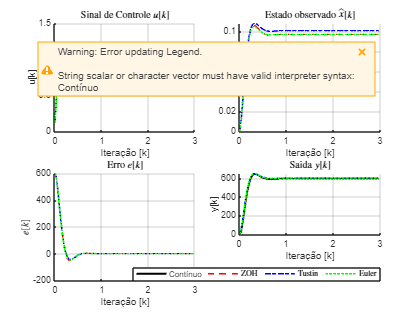

% Vetor de tempo (ajuste conforme sua simulação)
u = ones(size(t)); % Degrau unitário

[y_cl, time_cl, x_cl] = lsim(sys_cl, u, t);  % Contínuo
f = figure;

% --- Subplot 1: Sinal de Controle u[k]
subplot(2,2,1);
hold on;
plot(t, u_zoh, 'r--', 'LineWidth', 1.5); 
plot(t, u_tustin, 'b-.', 'LineWidth', 1.5);
plot(t, u_euler, 'g:', 'LineWidth', 1.5);
xlabel('Iteração [k]');
ylabel('u[k]');
title('Sinal de Controle $u[k]$', 'Interpreter', 'latex');
grid on;

% --- Subplot 2: Estado observado
subplot(2,2,2);
hold on;
plot(t, x_hat_zoh, 'r--', 'LineWidth', 1.5); 
plot(t, x_hat_tustin, 'b-.', 'LineWidth', 1.5);
plot(t, x_hat_euler, 'g:', 'LineWidth', 1.5);
xlabel('Iteração [k]');
ylabel('$\hat{x}[k]$', 'Interpreter', 'latex');
title('Estado observado $\hat{x}[k]$', 'Interpreter', 'latex');
grid on;

% --- Subplot 3: Erro
subplot(2,2,3);
hold on;
plot(t, e_log_zoh, 'r--', 'LineWidth', 1.5); 
plot(t, e_log_tustin, 'b-.', 'LineWidth', 1.5);
plot(t, e_log_euler, 'g:', 'LineWidth', 1.5);
xlabel('Iteração [k]');
ylabel('$e[k]$', 'Interpreter', 'latex');
title('Erro $e[k]$', 'Interpreter', 'latex');
grid on;

% --- Subplot 4: Saída
subplot(2,2,4);
hold on;
plot(t, y_cl * Kp, 'k-', 'LineWidth', 2, 'DisplayName', 'Contínuo');
plot(t, y_zoh_cl, 'r--', 'LineWidth', 1.5); 
plot(t, y_tustin_cl, 'b-.', 'LineWidth', 1.5);
plot(t, y_euler_cl, 'g:', 'LineWidth', 1.5);
xlabel('Iteração [k]');
ylabel('y[k]');
title('Saida $y[k]$', 'Interpreter', 'latex');
grid on;

% Legenda global abaixo da figura
lgd = legend({'Contínuo', 'ZOH', 'Tustin', 'Euler'}, ...
    'Orientation', 'horizontal', ...
    'Location', 'southoutside', ...
    'Interpreter', 'latex');

% Exporta tudo em um único PDF
exportgraphics(f, './Resultados/RespostaDiscreta.pdf', 'ContentType', 'vector');

Comparacao Eds simulação


% === 1. Calcula métricas com stepinfo ===
info_cont   = stepinfo(y_cl * Kp,     t);  % contínuo com ganho Kp
info_zoh    = stepinfo(y_zoh_cl,      t);
info_tustin = stepinfo(y_tustin_cl,   t);
info_euler  = stepinfo(y_euler_cl,    t);

% === 2. Vetores da Tabela ===
Method = {
    'Contínuo';
    'ZOH';
    'Tustin';
    'Euler';
    'Referência';
};

Overshoot = [
    info_cont.Overshoot;
    info_zoh.Overshoot;
    info_tustin.Overshoot;
    info_euler.Overshoot;
    up;
];

SettlingTime = [
    info_cont.SettlingTime;
    info_zoh.SettlingTime;
    info_tustin.SettlingTime;
    info_euler.SettlingTime;
    ts;
];

% === 3. Constrói coluna com sistemas como strings A,B,C,D ===
sistemas_list = {sys, sys_zoh, sys_tustin, sys_euler};
SistemasStr = cell(5,1);

for i = 1:4
    s = sistemas_list{i};
    A_str = mat2str(s.A, 4);
    B_str = mat2str(s.B, 4);
    C_str = mat2str(s.C, 4);
    D_str = mat2str(s.D, 4);
    SistemasStr{i} = sprintf('A=%s, B=%s, C=%s, D=%s', A_str, B_str, C_str, D_str);
end

% Linha da referência
SistemasStr{5} = '—';

% === 4. Criação da Tabela Final ===
T = table(Method, SistemasStr, Overshoot, SettlingTime, ...
    'VariableNames', {'Método', 'Sistema', 'Ultrapassagem(%)', 'TempoAcomodação(s)'});

% === 5. Exibição ===
disp('== Comparação de Desempenho ==');

== Comparação de Desempenho ==


disp(T);

        Método                       Sistema                   Ultrapassagem(%)    TempoAcomodação(s)
    ______________    _____________________________________    ________________    __________________

    {'Contínuo'  }    {'A=-10.42, B=1, C=6198, D=0'       }         8.3964                0.493      
    {'ZOH'       }    {'A=0.92, B=0.007676, C=6198, D=0'  }         8.6373               0.4928      
    {'Tustin'    }    {'A=0.92, B=0.00768, C=5950, D=23.8'}         7.2892               0.4951      
    {'Euler'     }    {'A=0.9167, B=0.008, C=6198, D=0'   }         7.9251              0.48405      
    {'Referência'}    {'—'                                }         8.4034               0.5244      



% === 6. Exportação para CSV ===
writetable(T, 'Comparacao_Desempenho.csv');

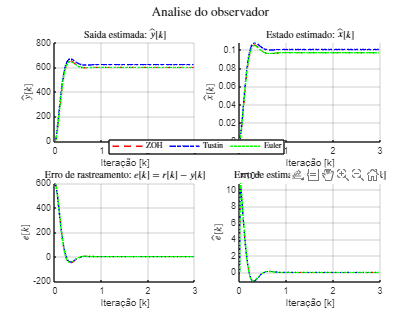

% Figura com 4 subplots
f = figure;

subplot(2,2,1);
hold on;
plot(t, y_hat_zoh, 'r--', 'LineWidth', 1.5); 
plot(t, y_hat_tustin, 'b-.', 'LineWidth', 1.5);
plot(t, y_hat_euler, 'g:', 'LineWidth', 1.5);
hold off;
title('Saida estimada: $\hat{y}[k]$', 'Interpreter', 'latex');
xlabel('Iteração [k]');
ylabel('$\hat{y}[k]$', 'Interpreter', 'latex');
grid on;

% 2. Estado x vs x_hat (1ª componente)
subplot(2,2,2);
hold on;
plot(t, x_hat_zoh, 'r--', 'LineWidth', 1.5); 
plot(t, x_hat_tustin, 'b-.', 'LineWidth', 1.5);
plot(t, x_hat_euler, 'g:', 'LineWidth', 1.5);
hold off;
title('Estado estimado: $\hat{x}[k]$', 'Interpreter', 'latex');
xlabel('Iteração [k]');
ylabel('$\hat{x}[k]$', 'Interpreter', 'latex');
grid on;

% 3. Erro de rastreamento e = r - y
subplot(2,2,3);
hold on;
plot(t, e_log_zoh, 'r--', 'LineWidth', 1.5); 
plot(t, e_log_tustin, 'b-.', 'LineWidth', 1.5);
plot(t, e_log_euler, 'g:', 'LineWidth', 1.5);
hold off;
title('Erro de rastreamento: $e[k] = r[k] - y[k]$', 'Interpreter', 'latex');
xlabel('Iteração [k]');
ylabel('$e[k]$', 'Interpreter', 'latex');
grid on;

% 4. Erro de estimação ê = x - x̂ (1ª componente)
subplot(2,2,4);
hold on;
plot(t, e_hat_zoh, 'r--', 'LineWidth', 1.5); 
plot(t, e_hat_zoh, 'b-.', 'LineWidth', 1.5);
plot(t, e_hat_euler, 'g:', 'LineWidth', 1.5);
hold off;
title('Erro de estimativa: $\hat{e}[k] = x[k] - \hat{x}[k]$', 'Interpreter', 'latex');
xlabel('Iteração [k]');
ylabel('$\hat{e}[k]$', 'Interpreter', 'latex');
grid on;

% Legenda global abaixo da figura
lgd = legend({'ZOH', 'Tustin', 'Euler'}, ...
    'Orientation', 'horizontal', ...
    'Location', 'southoutside', ...
    'Interpreter', 'latex');

% Título geral
sgtitle('Analise do observador', 'Interpreter', 'latex');

% Exporta para PDF vetorial
exportgraphics(f, './Resultados/ControllerAndObserver.pdf', 'ContentType', 'vector');